num_units = 0;
units_nwb_idx = [];
units_tbl_idx = [];
for ii = 1 : numel(nwb)

    units_per_nwb(ii) = sum(strcmp(nwb{ii}.units.vectordata.get('quality').data(:),'good')); 
    num_units = num_units + units_per_nwb(ii);
    units_nwb_idx = [units_nwb_idx repmat(ii, 1, units_per_nwb(ii))];
    units_tbl_idx = [units_tbl_idx find(strcmp(nwb{ii}.units.vectordata.get('quality').data(:),'good')).'];

end

units_per_nwb

units_per_nwb =      8    19     9    53    64    79    42    79    94     9    15    19   141


num_units

num_units = 631

idx_units = 36

idx_units = 36

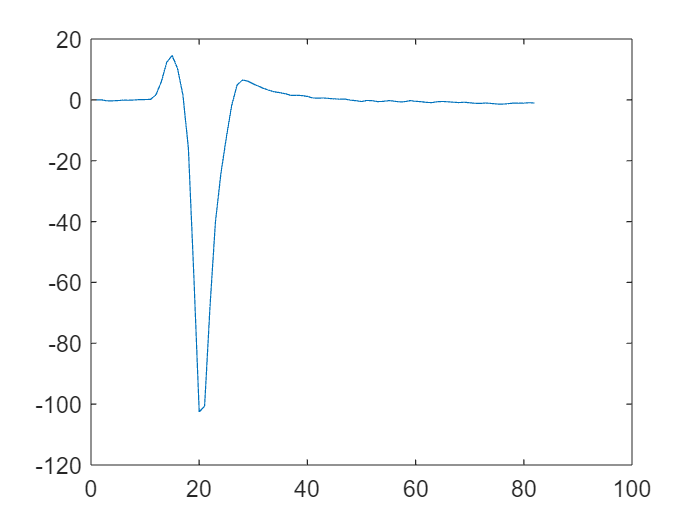


figure;
num_channels = numel(nwb{units_nwb_idx(idx_units)}.general_extracellular_ephys_electrodes.vectordata.get('probe').data(:));
nwb_waves = reshape(nwb{units_nwb_idx(idx_units)}.units.waveform_mean.data(:,:), 82, num_channels, []);
peak_channel = nwb{units_nwb_idx(idx_units)}.units.vectordata.get('peak_channel_id').data(units_tbl_idx(idx_units))+1;
plot(nwb_waves(:,peak_channel,units_tbl_idx(idx_units)))